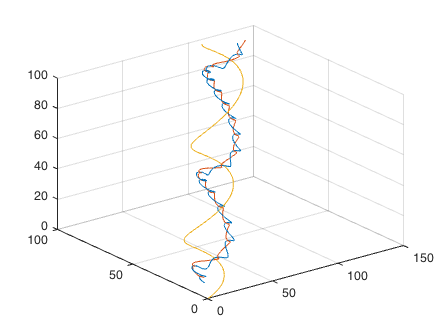

clc;
clear;
close all;
%Posiciones Iniciales
x0=[15 20 0];y0=[15 20 0];z0=[0 0 0];
%Velocidades Iniciales
x_0=[0 0 2.5];y_0=[4 0 0];z_0=[1 1 1]; G=39.478; g=9.8;
%Tiempos Inicial, Final y h,
t0=0;tf=100;h=.001;
%Masas 1(sol) 2(tierra) 3(satélite)
m1=1.5 ;m2=2.7;m3=3.2; M=m1+m2+m3;
%Llamando a la función para utilizar el método leapfrog
[x,y,z,x_,y_,z_,r12,r13,r23]=TresCuerpos(x0,y0,z0,x_0,y_0,z_0,t0,tf,h,m1,m2,m3);

%Graficando
plot3(x(1,:),y(1,:),z(1,:));
hold on
plot3(x(2,:),y(2,:),z(2,:));
hold on
plot3(x(3,:),y(3,:),z(3,:));
grid on
hold off


%Centro de masas
vector_Masa = zeros(3,length(t0:h:tf)+1);

vector_Masa(1,:) = (m1*x(1,:)+m2*x(2,:)+m3*x(3,:))./M;
vector_Masa(2,:) = (m1*y(1,:)+m2*y(2,:)+m3*y(3,:))./M;
vector_Masa(3,:) = (m1*z(1,:)+m2*z(2,:)+m3*z(3,:))./M;
%Velocidad del centro de masas
v_vector_Masa(1,:) = (m1*x_(1,:)+m2*x_(2,:)+m3*x_(3,:))./M;
v_vector_Masa(2,:) = (m1*y_(1,:)+m2*y_(2,:)+m3*y_(3,:))./M;
v_vector_Masa(3,:) = (m1*z_(1,:)+m2*z_(2,:)+m3*z_(3,:))./M;

%Conservación de la energía
T=zeros(1,length(t0:h:tf)+1);
U=T;
%Cálculo de la energía cinética
T(1,:)=(1/2)*M*(v_vector_Masa(1,:).^2+v_vector_Masa(2,:).^2 +v_vector_Masa(3,:).^2);
%Cálculo de la energía potencial
U(1,:)=- G * ((m1 * m2) / r12 + (m1 * m3) / r13 + (m2 * m3) / r23);
%Cálculo de la energía mecánica total
E=T+U;

function[x,y,z,x_,y_,z_,d12,d13,d23]=TresCuerpos(x0,y0,z0,x_0,y_0,z_0,t0,tf,h,m1,m2,m3)
% Declarando Tamaño de Vectores
x=zeros(3,length(t0:h:tf)); y=x; z=x;
x_=x;y_=x;z_=x;
xm_=x;ym_=x;zm_=x;
tv=x;
% Condiciones Iniciales
x(:,1)=[x0(1);x0(2);x0(3)];y(:,1)=[y0(1);y0(2);y0(3)];z(:,1)=[z0(1);z0(2);z0(3)];
x_(:,1)=[x_0(1);x_0(2);x_0(3)];y_(:,1)=[y_0(1);y_0(2);y_0(3)];z_(:,1)=[z_0(1);z_0(2);z_0(3)];
tv(1)=t0;

% Declarando Funciones Anónimas
G=39.478;
d = @(x1,y1,z1,x2,y2,z2) ((x1-x2)^2+(y1-y2)^2+(z1-z2)^2)^(1/2);
ab = @(x1,x2) (x1-x2);
A = @(a,b,d1,d2,M1,M2) -G*( M1*(a)/(d1^3) + M2*(b)/(d2^3)); 

    for i = 1:length(x(1,:))
            
        tv(i+1)= tv(i)+h;
        
        d12= d(x(1,i),y(1,i),z(1,i),x(2,i),y(2,i),z(2,i));
        d13= d(x(1,i),y(1,i),z(1,i),x(3,i),y(3,i),z(3,i));
        d23= d(x(2,i),y(2,i),z(2,i),x(3,i),y(3,i),z(3,i));
        
        xm_(:,i) = [x_(1,i)+ (1/2)*h*A(ab(x(1,i),x(2,i)),ab(x(1,i),x(3,i)),d12,d13,m2,m3);
                    x_(2,i)+ (1/2)*h*A(ab(x(2,i),x(1,i)),ab(x(2,i),x(3,i)),d12,d23,m1,m3);
                    x_(3,i)+ (1/2)*h*A(ab(x(3,i),x(1,i)),ab(x(3,i),x(2,i)),d13,d23,m1,m2)];
        
        ym_(:,i) = [y_(1,i)+ (1/2)*h*A(ab(y(1,i),y(2,i)),ab(y(1,i),y(3,i)),d12,d13,m2,m3);
                    y_(2,i)+ (1/2)*h*A(ab(y(2,i),y(1,i)),ab(y(2,i),y(3,i)),d12,d23,m1,m3);
                    y_(3,i)+ (1/2)*h*A(ab(y(3,i),y(1,i)),ab(y(3,i),y(2,i)),d13,d23,m1,m2)];
        
        zm_(:,i) = [z_(1,i)+ (1/2)*h*A(ab(z(1,i),z(2,i)),ab(z(1,i),z(3,i)),d12,d13,m2,m3);
                    z_(2,i)+ (1/2)*h*A(ab(z(2,i),z(1,i)),ab(z(2,i),z(3,i)),d12,d23,m1,m3);
                    z_(3,i)+ (1/2)*h*A(ab(z(3,i),z(1,i)),ab(z(3,i),z(2,i)),d13,d23,m1,m2)];
        
        
        x(:,i+1)= [x(1,i)+h*xm_(1,i);
                   x(2,i)+h*xm_(2,i);
                   x(3,i)+h*xm_(3,i)];
        
        y(:,i+1)= [y(1,i)+h*ym_(1,i);
                   y(2,i)+h*ym_(2,i);
                   y(3,i)+h*ym_(3,i)];
        
        z(:,i+1)= [z(1,i)+h*zm_(1,i);
                   z(2,i)+h*zm_(2,i);
                   z(3,i)+h*zm_(3,i)];
        
        d12= d(x(1,i+1),y(1,i+1),z(1,i+1),x(2,i+1),y(2,i+1),z(2,i+1));
        d13= d(x(1,i+1),y(1,i+1),z(1,i+1),x(3,i+1),y(3,i+1),z(3,i+1));
        d23= d(x(2,i+1),y(2,i+1),z(2,i+1),x(3,i+1),y(3,i+1),z(3,i+1));
        
        x_(:,i+1)=[xm_(1,i)+h*(1/2)*A(ab(x(1,i+1),x(2,i+1)),ab(x(1,i+1),x(3,i+1)),d12,d13,m2,m3);         
                   xm_(2,i)+h*(1/2)*A(ab(x(2,i+1),x(1,i+1)),ab(x(2,i+1),x(3,i+1)),d12,d23,m1,m3);
                   xm_(3,i)+h*(1/2)*A(ab(x(3,i+1),x(1,i+1)),ab(x(3,i+1),x(2,i+1)),d13,d23,m1,m2)];
        
        y_(:,i+1)=[ym_(1,i)+h*(1/2)*A(ab(y(1,i+1),y(2,i+1)),ab(y(1,i+1),y(3,i+1)),d12,d13,m2,m3);        
                   ym_(2,i)+h*(1/2)*A(ab(y(2,i+1),y(1,i+1)),ab(y(2,i+1),y(3,i+1)),d12,d23,m1,m3);
                   ym_(3,i)+h*(1/2)*A(ab(y(3,i+1),y(1,i+1)),ab(y(3,i+1),y(2,i+1)),d13,d23,m1,m2)];
        
        z_(:,i+1)=[zm_(1,i)+h*(1/2)*A(ab(z(1,i+1),z(2,i+1)),ab(z(1,i+1),z(3,i+1)),d12,d13,m2,m3);         
                   zm_(2,i)+h*(1/2)*A(ab(z(2,i+1),z(1,i+1)),ab(z(2,i+1),z(3,i+1)),d12,d23,m1,m3);
                   zm_(3,i)+h*(1/2)*A(ab(z(3,i+1),z(1,i+1)),ab(z(3,i+1),z(2,i+1)),d13,d23,m1,m2)];
    

        
    end
end